clc;clear;close all;

## 生成点

warning off

azimuth = 5.135899059569828;
elevation = 1.57897350050879;

r = 1;
x0 = r.*cos(azimuth).*cos(elevation);
y0 = r.*cos(azimuth).*sin(elevation);
z0 = r.*sin(azimuth);
Tao = [x0,y0,z0]

Tao =    -0.0034    0.4109   -0.9117


P3 = [0.698625642652000,1.04004032326448,-0.573794783259771]+Tao;
P4 = [0.710558671267955,-0.419236813348415,-0.777745273229581]-Tao;


num = 8;
laynum = 5;

% 测试 生成 一个截面 测点
Point_out = generate_unit_circle_with_normal_vector2(azimuth,elevation,num,laynum,P3,P4);


## 拟合圆柱

% 测试 测点的拟合
[Mcenter,MTaon,Mradial,Err_every,Bottom_round_center1,Bottom_round_center2]=Calculate_accurate_cylinders_from_multiple_measurement_points2(Point_out,P3,P4);

## A、B面点测试

testP = Point_out(:,20);
numShengLu = 4;
phi = pi/3;

toff = 0.05;
roff = 0.05;

[PointTable_A,PointTable_B] = Calculat_A_and_B_Points(MTaon',Mcenter',Mradial,Bottom_round_center1',Bottom_round_center2',testP,numShengLu,phi);
[PointTable_A_off,PointTable_B_off] = Calculat_A_and_B_Points_after_Offest(MTaon',Mcenter',Mradial,Bottom_round_center1',Bottom_round_center2',testP,numShengLu,phi,toff,roff)

PointTable_A_off =    -0.8382   -0.3558    0.3565    0.8365    0.8332    0.3508   -0.3615   -0.8415
   -0.0775   -0.3424   -0.3393   -0.0702    0.6877    0.9527    0.9496    0.6804
   -1.1657   -1.5165   -1.5165   -1.1657   -0.1881    0.1627    0.1627   -0.1881


PointTable_B_off =    -0.8372   -0.3540    0.3583    0.8376    0.8322    0.3490   -0.3633   -0.8426
   -0.3158   -0.7535   -0.7503   -0.3085    0.9261    1.3637    1.3606    0.9187
   -0.6383   -0.6069   -0.6069   -0.6383   -0.7155   -0.7469   -0.7469   -0.7155


## 绘图验证

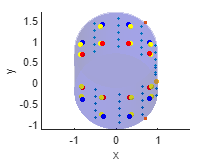

figure
hold on
% 绘制圆柱面
plotcylinder(Bottom_round_center1,Bottom_round_center2,'b',Mradial,0.2)
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
camlight;
lighting flat;

% 绘制散点
scatter3(Point_out(1,:),Point_out(2,:),Point_out(3,:),5,"filled");
scatter3([P3(1),P4(1)],[P3(2),P4(2)],[P3(3),P4(3)],10,"filled");


% quiver3(0,0,0,A(1),A(2),A(3))
% quiver3(0,0,0,B(1),B(2),B(3))
% quiver3(0,0,0,C(1),C(2),C(3))
% quiver3(0,0,0,D(1),D(2),D(3))



% scatter3(xN1,yN1,zN1,20,'filled')
scatter3(testP(1),testP(2),testP(3),20,'filled')
% plot3([xN1,testP(1)],[yN1,testP(2)],[zN1,testP(3)])


% scatter3(Tao2(1),Tao2(2),Tao2(3),20,'filled')
% plot3([xN1,Tao2(1)],[yN1,Tao2(2)],[zN1,Tao2(3)])
PointTable_A = PointTable_A';
PointTable_B = PointTable_B';


PointTable_A_off = PointTable_A_off';
PointTable_B_off = PointTable_B_off';

scatter3(PointTable_A(:,1),PointTable_A(:,2),PointTable_A(:,3),20,'filled','red')
scatter3(PointTable_B(:,1),PointTable_B(:,2),PointTable_B(:,3),20,'filled','blue')

scatter3(PointTable_A_off(:,1),PointTable_A_off(:,2),PointTable_A_off(:,3),20,'filled','yellow')
scatter3(PointTable_B_off(:,1),PointTable_B_off(:,2),PointTable_B_off(:,3),20,'filled','yellow')